warning('off')

toy_samples = 50;
nb_inputs = 2;
nb_outputs = 2;

bf = {@theta1, @theta2, @theta3, @theta4, @theta5, @theta6, @theta7, @theta8, @theta9, @theta10};
bfs = {bf, bf};
r = {6, 4};
sampling_points = randn(nb_inputs, toy_samples);

Jac1 = zeros(nb_outputs+1, nb_inputs, toy_samples);
Jac2 = zeros(nb_outputs, nb_inputs, toy_samples);
for i=1:toy_samples
    point = dlarray(sampling_points(:,i)');

    [~, Jac1(1,:,i)] = dlfeval(@f1, point);
    [~, Jac1(2,:,i)] = dlfeval(@f2, point);
    [~, Jac1(3,:,i)] = dlfeval(@f3, point);

    [~, Jac2(1,:,i)] = dlfeval(@f11, point);
    [~, Jac2(2,:,i)] = dlfeval(@f22, point);
end

[WList, HList, Clist] = generalCTD({Jac1; Jac2}, bfs, r, {sampling_points; sampling_points});

U1 = {WList{1}, WList{2}, HList{1}};
frob(cpdres(Jac1, U1)) / frob(Jac1)

ans = 0.2895


U2 = {WList{3}, WList{4}, HList{2}};
frob(cpdres(Jac2, U2)) / frob(Jac2)

ans = 0.0048

## Eerste laag

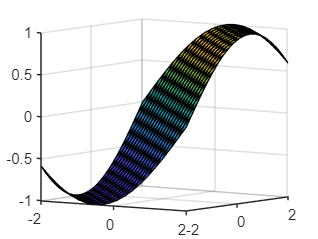


x = linspace(-2,2,20);
y = x';
z = zeros(20);
zb = zeros(20,20,3);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f1, point);
        zb(i,j,:) = fbar([x(i); y(j)], WList{1}, WList{2}, Clist{1}, r{1});
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

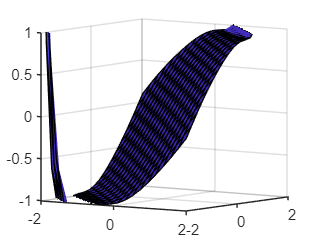

% Benadering
surf(x,y,zb(:,:,1))
view([35.05 6.20])
zlim([-1 1])

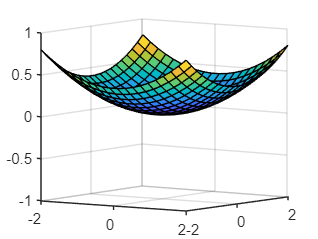



z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f2, point);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])
zlim([-1 1])

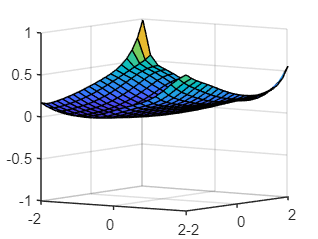

% Benadering
surf(x,y,zb(:,:,2))
view([35.05 6.20])
zlim([-1 1])

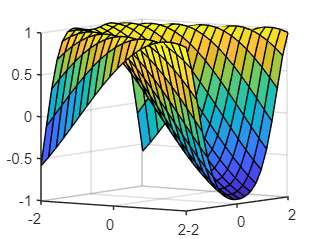


z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f3, point);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

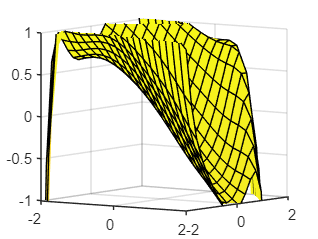

% Benadering
surf(x,y,zb(:,:,3))
view([35.05 6.20])
zlim([-1 1])

## Tweede laag

x = linspace(-2,2,20);
y = x';
z = zeros(20);
zb = zeros(20,20,2);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f11, point);
        zb(i,j,:) = fbar([x(i); y(j)], WList{3}, WList{4}, Clist{2}, r{2});
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

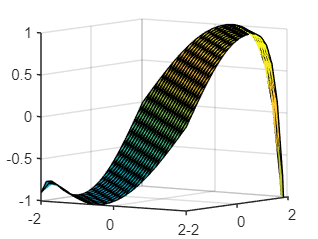

% Benadering
surf(x,y,zb(:,:,1))
view([35.05 6.20])
zlim([-1 1])

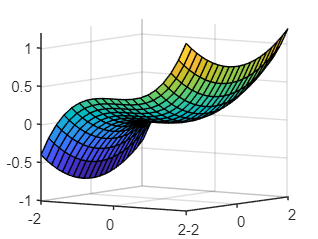



z = zeros(20);
for i=1:20
    for j=1:20
        point = dlarray([x(i), y(j)]);
        [z(i,j), ~] = dlfeval(@f22, point);
    end
end

% Origineel
surf(x,y,z)
view([35.05 6.20])

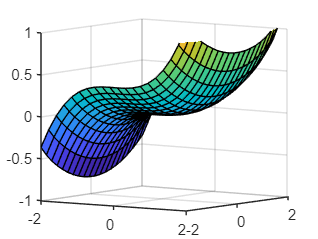

% Benadering
surf(x,y,zb(:,:,2))
view([35.05 6.20])
zlim([-1 1])

## Interpratie als neuraal netwerk met 2 lagen flexibele activatie functies

u = dlarray([0.2, 0.2]);

u_int = dlarray([dlfeval(@f1, u) ; dlfeval(@f2, u)]);
u_final = [dlfeval(@f11, u_int) ; dlfeval(@f22, u_int)]

u_final =   2×1 dlarray

    0.1606
    0.0062



V0 = WList{3};
V1trans = WList{4}' * WList{1};
V2 = WList{2};

first_layer = fbar(u',V1trans,V2,Clist{1},r{1});
fbar(first_layer,V0,eye(4),Clist{2},r{2})

ans =     0.1601
    0.0062


function [f,grad] = f1(x)
    f = sin(0.2 * pi * (x(1) + x(2))); %2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f,grad] = f11(x)
    f = sin(0.2 * pi * (x(1) + x(2))); %2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f,grad] = f2(x)
    f = 0.1*x(1)^2 + 0.1*x(2)^2; %tanh(prod(x)); %-5 + tanh(sum(x));
    grad = dlgradient(f,x);
end


function [f,grad] = f22(x)
    f = 0.1*x(1)^2 + 0.1*x(2)^3; %tanh(sum(x)); %-5 + tanh(sum(x));
    grad = dlgradient(f,x);
end

function [f,grad] = f3(x)
    f = sin(0.2 * pi * (x(1)^2 - x(2))); %2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end

function [f,grad] = f33(x)
    f =  0.1*x(1)^3 - 0.1*x(2)^2; %2.5 + sin(0.2 * pi * (x(1) + x(2)));
    grad = dlgradient(f,x);
end


function [f] = fbar(u, W, V, c_toy, r)
    P = zeros(r,1);
    x = V' * u;
    for i=1:r
        P(i,1) = c_toy((10* (i - 1)) + 1) * x(i) + ...
                 c_toy((10* (i - 1)) + 2) * x(i)^2 + ...
                 c_toy((10* (i - 1)) + 3) * x(i)^3 + ...
                 c_toy((10* (i - 1)) + 4) * x(i)^4 + ...
                 c_toy((10* (i - 1)) + 5) * x(i)^5 + ...
                 c_toy((10* (i - 1)) + 6) * x(i)^6 + ...
                 c_toy((10* (i - 1)) + 7) * x(i)^7 + ...
                 c_toy((10* (i - 1)) + 8) * x(i)^8 + ...
                 c_toy((10* (i - 1)) + 9) * x(i)^9 + ...
                 c_toy((10* (i - 1)) + 10) * x(i)^10;
    end
    f = W * P;
end

function [f,grad] = theta1(x)
    f = x;
    grad = dlgradient(f,x);
end

function [f,grad] = theta2(x)
    f = x^2;
    grad = dlgradient(f,x);
end

function [f,grad] = theta3(x)
    f = x^3;
    grad = dlgradient(f,x);
end

function [f,grad] = theta4(x)
    f = x^4;
    grad = dlgradient(f,x);
end

function [f,grad] = theta5(x)
    f = x^5;
    grad = dlgradient(f,x);
end

function [f,grad] = theta6(x)
    f = x^6;
    grad = dlgradient(f,x);
end

function [f,grad] = theta7(x)
    f = x^7;
    grad = dlgradient(f,x);
end

function [f,grad] = theta8(x)
    f = x^8;
    grad = dlgradient(f,x);
end

function [f,grad] = theta9(x)
    f = x^9;
    grad = dlgradient(f,x);
end

function [f,grad] = theta10(x)
    f = x^10;
    grad = dlgradient(f,x);
end